Randomly generate normally distributed data into two matrices. The number of rows can vary, but the number of columns must be equal.

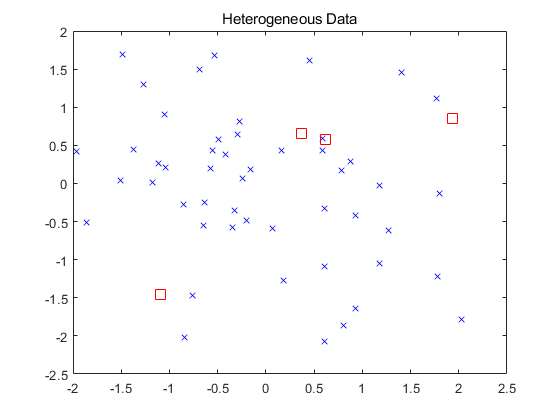

rng(1) % For reproducibility
X = randn(50,2);
Y = randn(4,2);

h = zeros(3,1);
figure
h(1) = plot(X(:,1),X(:,2),'bx');
hold on
h(2) = plot(Y(:,1),Y(:,2),'rs','MarkerSize',10);
title('Heterogeneous Data')

distance function

w = [0.4; 0.6];
chiSqrDist = @(x,Z)sqrt((bsxfun(@minus,x,Z).^2)*w);

Find the indices of the three nearest observations in X to each observation in Y.

k = 3;
[Idx,D] = knnsearch(X,Y,'Distance',chiSqrDist,'k',k);



Identify the nearest observations in the plot.

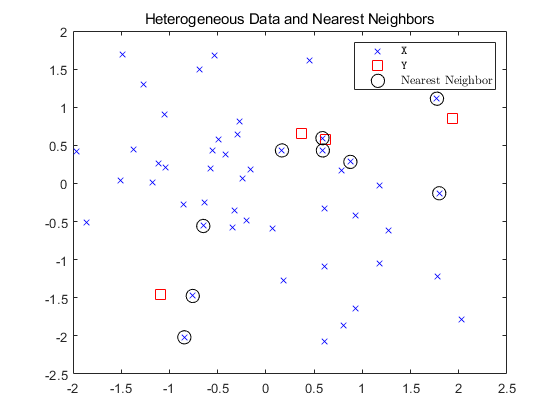

for j = 1:k
    h(3) = plot(X(Idx(:,j),1),X(Idx(:,j),2),'ko','MarkerSize',10);
end 
legend(h,{'\texttt{X}','\texttt{Y}','Nearest Neighbor'},'Interpreter','latex')
title('Heterogeneous Data and Nearest Neighbors')
hold off